data_load = load("generatedChannel_TDL_A_300_simple\SNR_5dB\matlabNTN.mat");

## Considering idx-th sample only

idx = 2 ;

### H perfect original sample idx

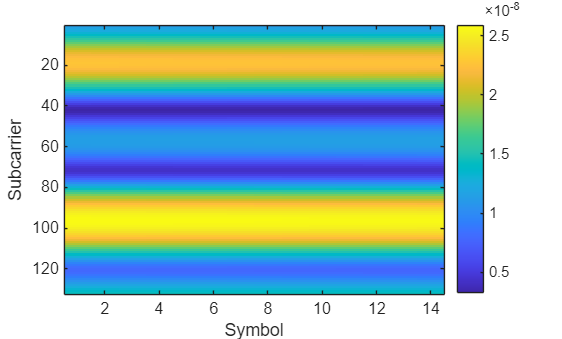

imagesc(abs(H_perfect_ori(:,:,idx).')); 
xlabel('Symbol'); ylabel('Subcarrier'); colorbar

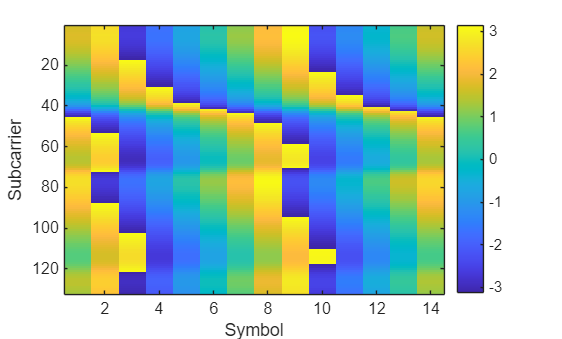

imagesc(angle(H_perfect_ori(:,:,idx).')); 
xlabel('Symbol'); ylabel('Subcarrier'); colorbar

### H effective sample idx

imagesc(abs(H_perfect(:,:,idx).')); 
xlabel('Symbol'); ylabel('Subcarrier'); colorbar

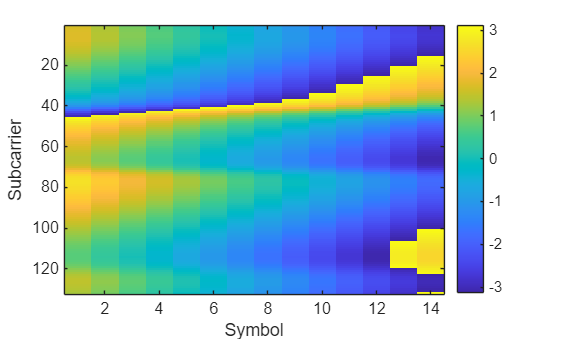

imagesc(angle(H_perfect(:,:,idx).')); 
xlabel('Symbol'); ylabel('Subcarrier'); colorbar

### Distribution

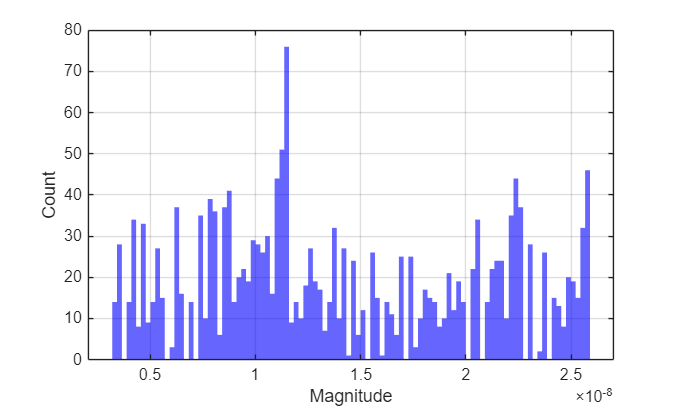

H_ori_idx = H_perfect_ori(:,:,idx).';
mag_data_ori = abs(H_ori_idx(:));
phase_data_ori = angle(H_ori_idx(:));

% figure;

% 2. Magnitude Histogram
figure
% subplot(1,2,1);
histogram(mag_data_ori, 'NumBins', 100, 'FaceColor', [0, 0, 1], 'EdgeColor','none'); % blue
% title('Distribution of Magnitude |H|');
xlabel('Magnitude');
ylabel('Count');
grid on;

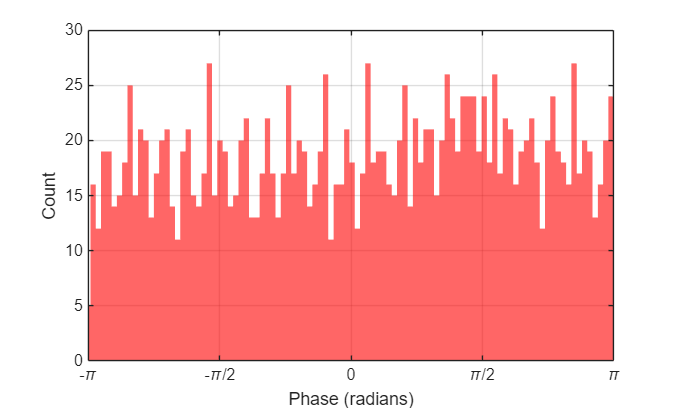


% 3. Phase Histogram
figure
% subplot(1,2,2);
histogram(phase_data_ori, 'NumBins', 100, 'FaceColor', [1, 0, 0], 'EdgeColor','none'); % Professional orange
% title('Distribution of Phase \angle H');
xlabel('Phase (radians)');
ylabel('Count');

% Format the phase axis for clarity
xlim([-pi, pi]);
xticks([-pi, -pi/2, 0, pi/2, pi]);
xticklabels({'-\pi', '-\pi/2', '0', '\pi/2', '\pi'});
grid on;

Effective channel

H_perfect_idx = H_perfect(:,:,idx).';
mag_data_perf = abs(H_perfect_idx(:));
phase_data_perf = angle(H_perfect_idx(:));
% 2. Magnitude Histogram
figure
% subplot(1,2,1);
histogram(mag_data_perf, 'NumBins', 100, 'FaceColor', [0, 0, 1], 'EdgeColor','none'); % blue
% title('Distribution of Magnitude |H|');
xlabel('Magnitude');
ylabel('Count');
grid on;

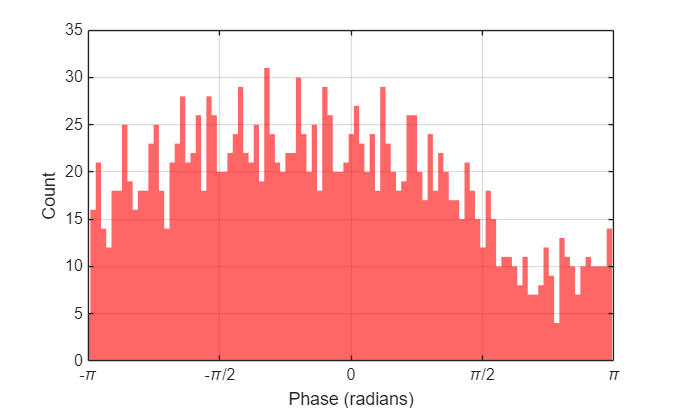


% 3. Phase Histogram
figure
% subplot(1,2,2);
histogram(phase_data_perf, 'NumBins', 100, 'FaceColor', [1, 0, 0], 'EdgeColor','none'); % Professional orange
% title('Distribution of Phase \angle H');
xlabel('Phase (radians)');
ylabel('Count');

% Format the phase axis for clarity
xlim([-pi, pi]);
xticks([-pi, -pi/2, 0, pi/2, pi]);
xticklabels({'-\pi', '-\pi/2', '0', '\pi/2', '\pi'});
grid on;

## Dataset

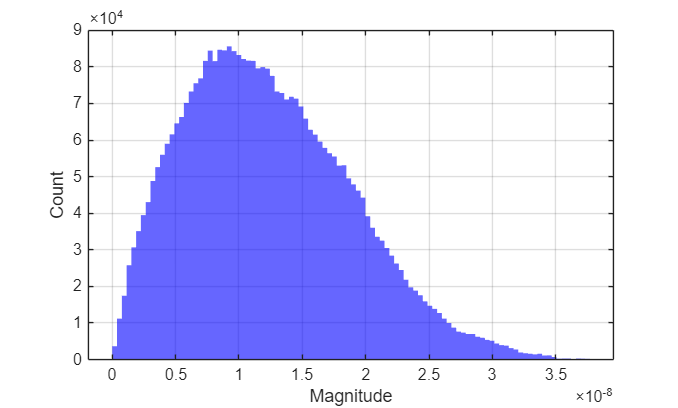

mag_data_ori = abs(H_perfect_ori(:));
phase_data_ori = angle(H_perfect_ori(:));

% figure;

% 2. Magnitude Histogram
figure
% subplot(1,2,1);
histogram(mag_data_ori, 'NumBins', 100, 'FaceColor', [0, 0, 1], 'EdgeColor','none'); % blue
% title('Distribution of Magnitude |H|');
xlabel('Magnitude');
ylabel('Count');
grid on;

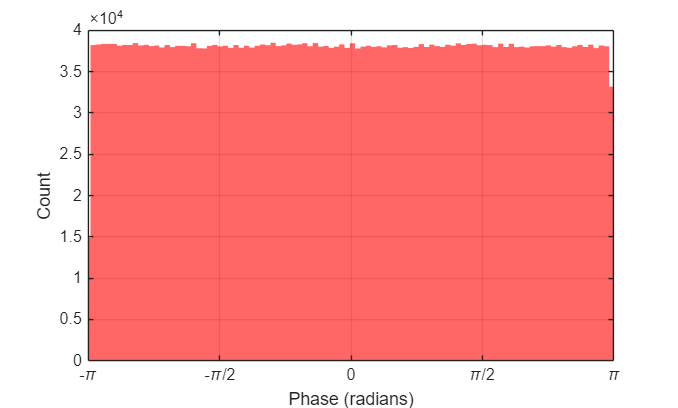

% 3. Phase Histogram
figure
% subplot(1,2,2);
histogram(phase_data_ori, 'NumBins', 100, 'FaceColor', [1, 0, 0], 'EdgeColor','none'); % Professional orange
% title('Distribution of Phase \angle H');
xlabel('Phase (radians)');
ylabel('Count');

% Format the phase axis for clarity
xlim([-pi, pi]);
xticks([-pi, -pi/2, 0, pi/2, pi]);
xticklabels({'-\pi', '-\pi/2', '0', '\pi/2', '\pi'});
grid on;

mag_data_perf = abs(H_perfect(:));
phase_data_perf = angle(H_perfect(:));
% 2. Magnitude Histogram
figure
% subplot(1,2,1);
histogram(mag_data_perf, 'NumBins', 100, 'FaceColor', [0, 0, 1], 'EdgeColor','none'); % blue
% title('Distribution of Magnitude |H|');
xlabel('Magnitude');
ylabel('Count');
grid on;

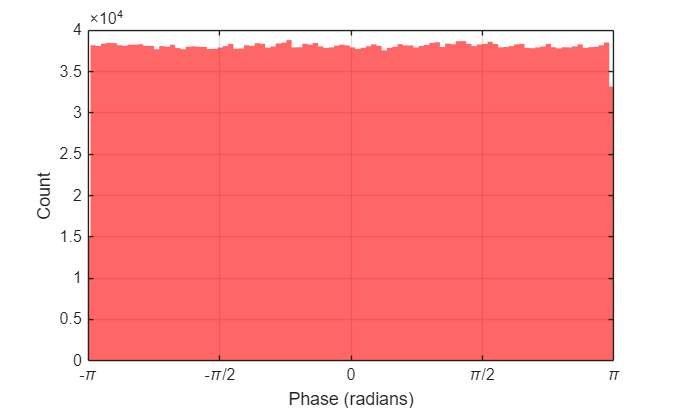


% 3. Phase Histogram
figure
% subplot(1,2,2);
histogram(phase_data_perf, 'NumBins', 100, 'FaceColor', [1, 0, 0], 'EdgeColor','none'); % Professional orange
% title('Distribution of Phase \angle H');
xlabel('Phase (radians)');
ylabel('Count');

% Format the phase axis for clarity
xlim([-pi, pi]);
xticks([-pi, -pi/2, 0, pi/2, pi]);
xticklabels({'-\pi', '-\pi/2', '0', '\pi/2', '\pi'});
grid on;